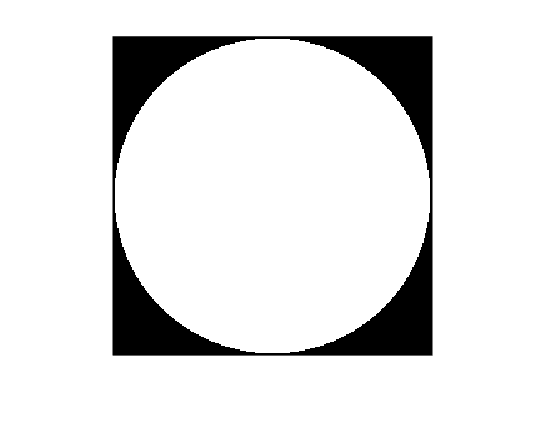

%% ==================== Part 1: Phase Unwrapping ====================
clc; clear; close all;

% Parameters
imgSize = 256;
numFrames = 300;
inputFolder = 'simu_test/test_UMNet/wrapped/';
outputFolder = 'simu_test/test_UMNet/unwrapped/';

% Generate circular pupil mask
[rhox, rhoy] = meshgrid(linspace(-1, 1, imgSize));
radius = 0.99;
circle = rhox.^2 + rhoy.^2;
circ_mask = double(circle <= radius^2);  % Binary mask inside the unit circle
imshow(circ_mask);


% Process each wrapped phase image
for idx = 0:numFrames-1
    % Read and scale wrapped phase [-pi, pi]
    imgPath = fullfile(inputFolder, [num2str(idx), '.png']);
    wrapped = double(imread(imgPath)) / 65535;
    wrapped = 2*pi*wrapped - pi;

    % Apply mask and unwrap
    wphs.data = wrapped .* circ_mask;
    wphs.mask = circ_mask;
    W_unwrap = unwrap(wphs, 0.001, 100);
    unwrapped = W_unwrap.data;

    % Normalize to [0,1] for saving
    unwrappedNorm = (unwrapped + 30) / 60;
    imwrite(unwrappedNorm .* circ_mask, ...
        fullfile(outputFolder, [num2str(idx), '.png']), ...
        'bitdepth', 16);
end


%% ==================== Part 2: Performance Evaluation ====================
clc; clear; close all;

% Parameters
imgSize = 256;
numFrames = 300;

% Generate circular pupil mask
[rhox, rhoy] = meshgrid(linspace(-1, 1, imgSize));
radius = 0.99;
circle = rhox.^2 + rhoy.^2;
mask = double(circle <= radius^2);

% File paths
phiPath = 'simu_test/phi/';
unwrapPath = 'simu_test/test_UMNet/unwrapped/';
paths = {phiPath, unwrapPath};

% Metrics storage
rmseVals = zeros(numFrames, 1);
ssimVals = zeros(numFrames, 1);
psnrVals = zeros(numFrames, 1);
pvVals   = zeros(numFrames, 1);

% Evaluate each frame
for idx = 0:numFrames-1
    % ---------- Ground Truth (phi) ----------
    gtPath = fullfile(paths{1}, [num2str(idx), '.png']);
    gt = im2double(imread(gtPath));
    gt = gt * 60 - 30;         % Scale back to [-30, 30]
    gt(gt == -30) = Inf;      % Avoid background contamination
    gt = gt .* mask;

    % ---------- Prediction (unwrapped) ----------
    predPath = fullfile(paths{2}, [num2str(idx), '.png']);
    pred = im2double(imread(predPath));
    pred = pred * 60 - 30;
    pred = pred .* mask;

    % ---------- Negative Prediction (for phase sign ambiguity) ----------
    predNeg = -pred;

    % ---------- Mean removal (align zero reference) ----------
    diffPos = pred - gt; diffPos(diffPos == 0) = NaN;
    pred = pred - mean(diffPos, 'omitnan');

    diffNeg = predNeg - gt; diffNeg(diffNeg == 0) = NaN;
    predNeg = predNeg - mean(diffNeg, 'omitnan');

    % Apply mask again after mean subtraction
    pred = pred .* mask;
    predNeg = predNeg .* mask;

    % Replace NaN with 0 for metric calculation
    pred(isnan(pred)) = 0;
    predNeg(isnan(predNeg)) = 0;
    gt(isnan(gt)) = 0;

    % ---------- Metrics ----------
    rmsePos = sqrt(mse(pred, gt)) / (2*pi);
    rmseNeg = sqrt(mse(predNeg, gt)) / (2*pi);
    rmseVals(idx+1) = min(rmsePos, rmseNeg);

    dynamicRange = max(gt(:)) - min(gt(:));

    ssimPos = ssim(pred, gt, 'DynamicRange', dynamicRange);
    ssimNeg = ssim(predNeg, gt, 'DynamicRange', dynamicRange);
    ssimVals(idx+1) = max(ssimPos, ssimNeg);

    psnrPos = psnr(pred, gt, dynamicRange);
    psnrNeg = psnr(predNeg, gt, dynamicRange);
    psnrVals(idx+1) = max(psnrPos, psnrNeg);

    pvPos = (max(pred(:) - gt(:)) - min(pred(:) - gt(:))) / (2*pi);
    pvNeg = (max(predNeg(:) - gt(:)) - min(predNeg(:) - gt(:))) / (2*pi);
    pvVals(idx+1) = min(pvPos, pvNeg);
end

% ---------- Average Metrics ----------
fprintf('Average RMSE  : %.4f λ\n', mean(rmseVals));

Average RMSE  : 0.0093 λ


fprintf('Average PV    : %.4f λ\n', mean(pvVals));

Average PV    : 0.5624 λ


fprintf('Average SSIM  : %.4f\n',   mean(ssimVals));

Average SSIM  : 0.9983


fprintf('Average PSNR  : %.4f dB\n', mean(psnrVals));

Average PSNR  : 56.3100 dB
